# Chapter 4, Section 2 (Part 2)

Here is an important theorem.

# Theorem 1

Let $V$ and $W$ be vector spaces and let $B=\left\{\vec v_1,\ \ldots,\ \vec v_n\right\}$ be a basis for the vector space $V$. If $T:\, V\rightarrow W$ is a linear transformation, then 

$R(T)=\text{span}\left\{T(\vec v_1),\, \ldots,\ T(\vec v_n)\right\}$.

**Proof:** To show that $R(T)=\text{span}\left\{T(\vec v_1),\, \ldots,\ T(\vec v_n)\right\}$, we need to show two things:

- 
$$R(T)\subset\text{span}\left\{T(\vec v_1),\, \ldots,\ T(\vec v_n)\right\}$$


- 
$$\text{span}\left\{T(\vec v_1),\, \ldots,\ T(\vec v_n)\right\}\subset R(T)$$


**Part 1: ** Let $\vec w\in R(T)$. Then there exists a vector $\vec v\in V$ so that $T(\vec v)=\vec w$.  Since $B=\left\{\vec v_1,\ \ldots,\ \vec v_n\right\}$ is a basis for $V$, there exists a linear combination


$$\vec v=c_1\vec v_1+\cdots+c_n\vec v_n$$


Therefore, we can write:


$$\begin{array}{rcl}
\vec w&=&T(\vec v)\\
&=&T(c_1\vec v_1+\cdots+c_n\vec v_n)\\
&=&c_1T(\vec v_1)+\cdots+c_nT(\vec v_n)
\end{array}$$


Therefore, we've shown that $\vec w\in \text{span}\left\{T(\vec v_1),\ \ldots,\ T(\vec v_n)\right\}$; that is, $R(T)\subset\text{span}\left\{T(\vec v_1),\, \ldots,\ T(\vec v_n)\right\}$.

**Part 2: **Let $\vec w\in \text{span}\left\{T(\vec v_1),\ \ldots,\ T(\vec v_n)\right\}$.  Therefore, there exists a linear combination


$$\vec w=c_1T(\vec v_1)+\cdot+c_nT(\vec v_n)$$


and because $T$ is a linear transformatioin, this can be written as:


$$\begin{array}{rcl}
\vec w&=&T(c_1\vec v_1+\cdots+c_n\vec v_n)
\end{array}$$


Because $B=\left\{\vec v_1,\ \ldots,\ \vec v_n\right\}$ is a basis for $V$,  $c_1\vec v_1+\cdots+c_n\vec v_n\in V$. Therefore, we've shown that $\vec w\in R(T)$; that is, we've shown that $\text{span}\left\{T(\vec v_1),\, \ldots,\ T(\vec v_n)\right\}\subset R(T)$.

Since we've shown that both part 1 and part 2 are true, we've shown that $R(t)=\text{span}\left\{T(\vec v_1),\, \ldots,\ T(\vec v_n)\right\}$. We're done.

# Example #1

Let $T: \mathbb R^3\rightarrow \mathbb R^3$ be a linear transformation and let $B=\left\{\vec v_1,\ \vec v_2,\ \vec v_3\right\}$ be a basis for $\mathbb R^3$.  Given that


$$T(\vec v_1)=\pmatrix{1\cr -1\cr 1},\qquad T(\vec v_2)=\pmatrix{2\cr 1 \cr 2},\qquad\text{and}\qquad T(\vec v_3)=\pmatrix{8\cr 1\cr 8}$$


answer each of the following questions.

- Is $\pmatrix{4\cr 2\cr 1}\in R(T)$?

- Find a basis for $R(T)$ and $\text{dim}(R(T))$.

- Find a basis for $N(T)$ and $\text{dim}(N(T))$.

**Solution:** 

**Part 1:** Recall that we just proved that $R(T)=\text{span}\left\{T(\vec v_1),\ \ldots,\ T(\vec v_n)\right\}$. Therefore, in order that $\pmatrix{4\cr 2\cr 1}\in R(T)$, we need to show that it can be written as a linear combination of $T(\vec v_1),\ T(\vec v_2),\ T(\vec v_3)$.


$$\begin{array}{rcl}
c_1T(\vec v_1)+c_2T(\vec v_2)+c_3T(\vec v_3)&=&\vec w\\
c_1\pmatrix{1\cr -1\cr 1}+c_2\pmatrix{2\cr 1\cr 2}+c_3\pmatrix{8\cr 1\cr 8}&=&\pmatrix{4\cr 2\cr 1}
\end{array}$$


Set up the augmented matrix and row reduce.


$$\pmatrix{1 & 2 & 8 & 4\cr -1 & 1 & 1 & 2\cr 1 & 2 & 8 & 1}\ \matrix{~\cr R_2+R_1\cr R_3-R_1}\qquad\longrightarrow\qquad\pmatrix{1 & 2 & 8 & 4\cr 0 & 3 & 9 & 6\cr 0 & 0 & 0 & -3}$$


We can check this with Matlab.

A=[1 2 8 4;-1 1 1 2;1 2 8 1];
r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1;r2+r1;r3-r1]

A =      1     2     8     4
     0     3     9     6
     0     0     0    -3


Correct thus far. Note that the last row represents 

$0c_1+0c_2+0c_3=-3$, so this system has no solutions. Hence, $\vec w\not\in R(T)$.

**Part 2: ** Theorem 1 says that $R(T)=\text{span}\left\{T(\vec v_1),\, \ldots,\ T(\vec v_n)\right\}$, so let's find a basis for


$$R(T)=\text{span}\left\{T(\vec v_1),\, \ldots,\ T(\vec v_n)\right\}=\text{span}\left\{\pmatrix{1 \cr -1\cr 1},\ \pmatrix{2\cr 1\cr 2},\ \pmatrix{8\cr 1\cr 8}\right\}$$


Create a matrix with the columns of $R(T)=\text{span}\left\{T(\vec v_1),\, \ldots,\ T(\vec v_n)\right\}$ and row reduce.


$$\pmatrix{1 & 2 & 8 \cr -1 & 1 & 1 \cr 1 & 2 & 8 }\ \matrix{~\cr R_2+R_1\cr R_3-R_1}\qquad\longrightarrow\qquad\pmatrix{1 & 2 & 8 \cr 0 & 3 & 9 \cr 0 & 0 & 0 }$$


We can check this with Matlab.

A=[1 2 8;-1 1 1;1 2 8];
r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1;r2+r1;r3-r1]

A =      1     2     8
     0     3     9
     0     0     0


Note that the first and second columns of


$$\pmatrix{[1] & 2 & 8 \cr 0 & [3] & 9 \cr 0 & 0 & 0 }$$


are pivot columns (therefore linearly independent), so we will pick columns one and two of 


$$\pmatrix{1 & 2 & 8 \cr -1 & 1 & 1 \cr 1 & 2 & 8 }$$


as the basis for $R(T)$.


$$B_{R(T)}=\left\{\pmatrix{1\cr -1\cr 1},\ \pmatrix{2\cr 1\cr 2}\right\}$$


Therefore, $\text{dim}(R(T))=2$.

# Visualize Our Answer

Now, is our answer correct? Does what we are doing make sense? We are saying that our transformation $T: \mathbb R^3\rightarrow \mathbb R^3$ maps all vectors in $\mathbb R^3$ onto 


$$R(T)=\text{span}\left\{\pmatrix{1\cr -1\cr 1},\ \pmatrix{2\cr 1\cr 2}\right\}$$


We know that this span of two vectors is a plane. Let's sketch this plane.


$$\begin{array}{rcl}
\pmatrix{x\cr y\cr z}&=&s\pmatrix{1\cr -1\cr 1}+t\pmatrix{2\cr 1\cr 2}\\
\pmatrix{x\cr y\cr z}&=&\pmatrix{s+2t\cr -s+t\cr s+2t}
\end{array}$$


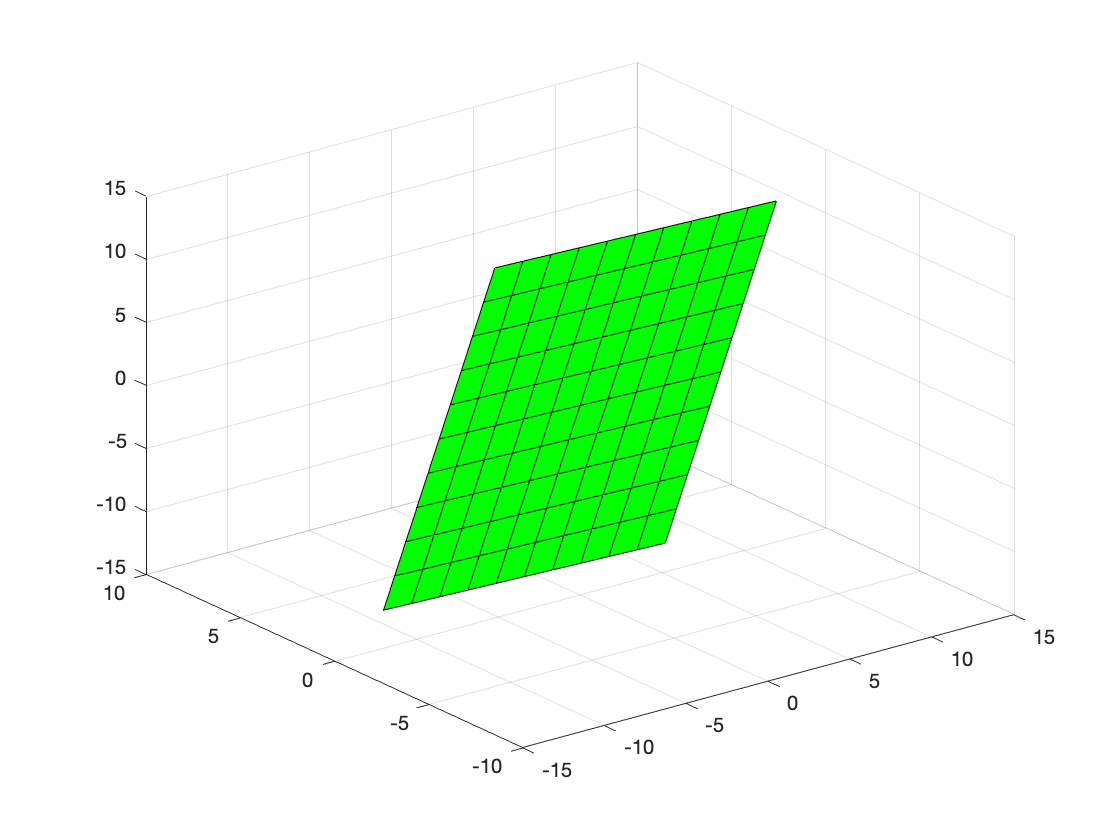

[S,T]=meshgrid(linspace(-4,4,11));
X=S+2*T;
Y=-S+T;
Z=S+2*T;
surf(X,Y,Z,'FaceColor','green')

Now, enter the matrix $A=\left[T(\vec v_1),\ T(\vec v_2),\ T(\vec v_3)\right]$.

A=[1 2 8;-1 1 1;1 2 8]

A =      1     2     8
    -1     1     1
     1     2     8


Since $T$ can be defined by $T(\vec x)=A\vec x$, let's create some random points in $\mathbb R^3$, then apply the transformation $T(\vec x)=A\vec x$ to the points and see if they all land on the plane above, which we claim is the range of $T$. The command rand(3,5) returns a $3\times 5$ matrix with random numbers between 0 and 1 inclusive, so -2*rand(3,5) returns a $3\times 5$ matrix with random numbers between -2 and 0 inclusive. Finally, 1-2*rand(3,5) returns a $3\times 5$ matrix with random numbers beween -1 and 1 inclusive.

pts=1-2*rand(3,5)

pts =    -0.1076   -0.5176    0.3381    0.6410   -0.0472
   -0.6848   -0.3520   -0.0370   -0.6948    0.5346
    0.9022   -0.7489    0.0921    0.9071   -0.8065


Now, we can apply our linear transformation to each of these points. Recall the property $AB=[A\vec b_1,\  \ldots,\ A\vec b_n]$ that says the matrix product $AB$ is obtained by multiplying matrix $A$ times each column of matrix $B$. Because each column of the matrix pts is a point in $\mathbb R^3$, Tpts=A*pts will apply our linear transformation to each column of pts.

Tpts=A*pts

Tpts =     5.7401   -7.2125    1.0010    6.5086   -5.4304
    0.3250   -0.5832   -0.2830   -0.4286   -0.2248
    5.7401   -7.2125    1.0010    6.5086   -5.4304


Now, let's add these points to our image. Note thtat the first row of Tpts contains the x-values of each point, the second row of Tpts contains the y-values of each point, and the third row of Tpts contains the z-values of each point. Matlab's scatter3(X,Y,Z) produces a scatter plot of points defined by the vectors X, Y, and Z, so scatter3(Tpts(1,:),Tpts(2,:),Tpts(3,:),'filled') uses the first, second, and third rows of Tpts to plot the transform of all of our random points.

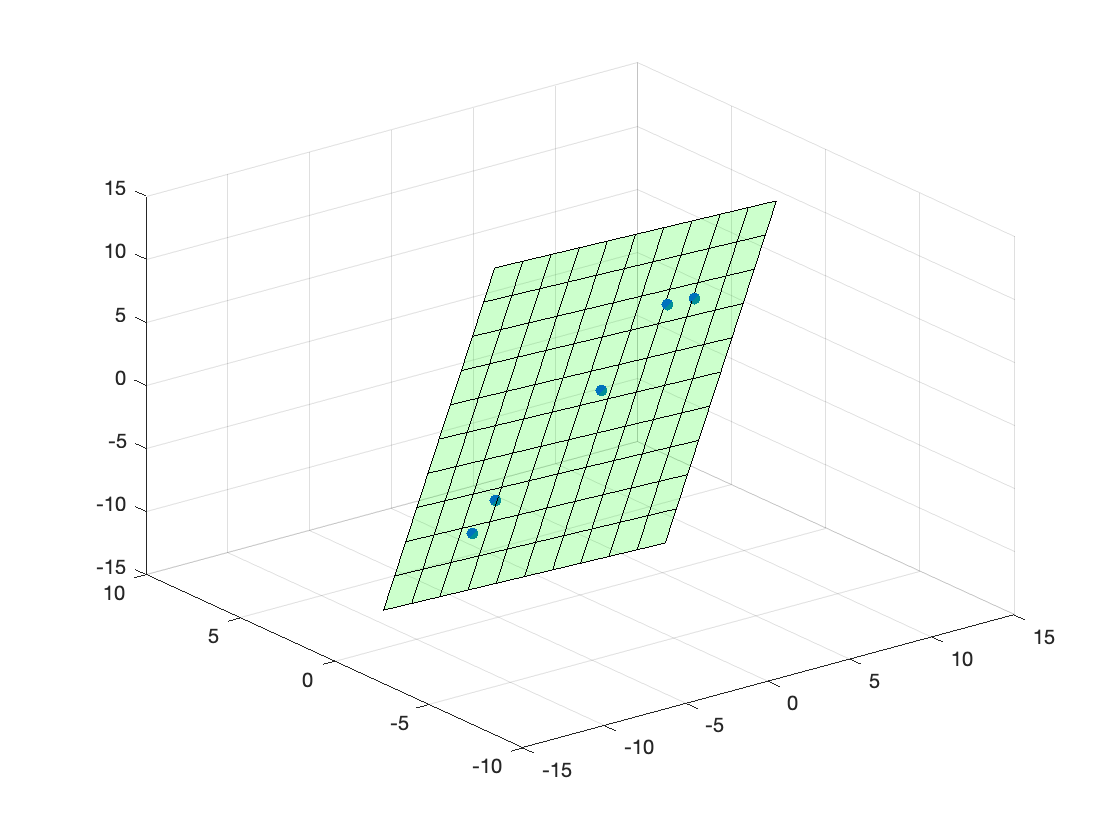

figure
[S,T]=meshgrid(linspace(-4,4,11));
X=S+2*T;
Y=-S+T;
Z=S+2*T;
surf(X,Y,Z,'FaceColor','green','FaceAlpha',0.2), hold on
scatter3(Tpts(1,:),Tpts(2,:),Tpts(3,:),'filled')
hold off

They all lie in the plane. Now, let's plot a lot of points.

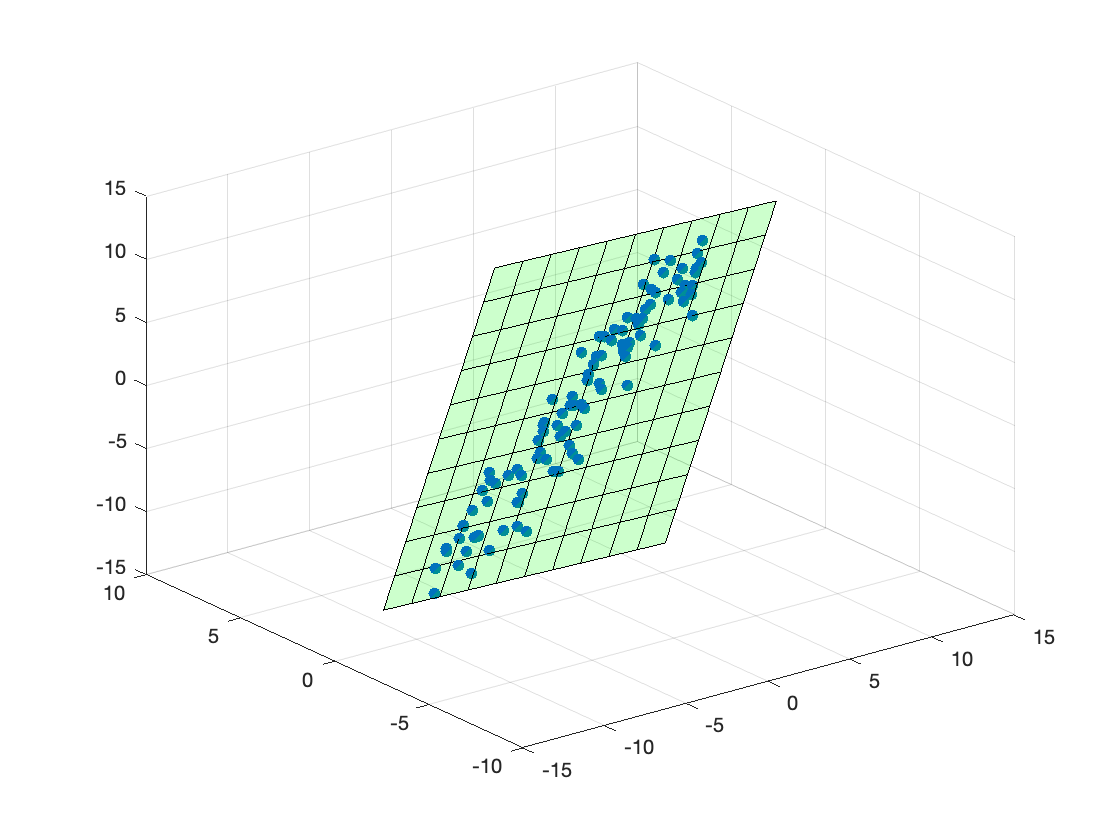

A=[1 2 8;-1 1 1;1 2 8];
pts=1-2*rand(3,100);
Tpts=A*pts;
figure
[S,T]=meshgrid(linspace(-4,4,11));
X=S+2*T;
Y=-S+T;
Z=S+2*T;
surf(X,Y,Z,'FaceColor','green','FaceAlpha',0.2), hold on
scatter3(Tpts(1,:),Tpts(2,:),Tpts(3,:),'filled')
hold off

Yes, they all lie in the plane (rotate the plane to make this even more clear), so our interpretation of the range of $T$ is correct. 

**Part 3:** By Theorem 1 above, the nullspace of our transformation $T:\, \mathbb R^3\rightarrow \mathbb R^3$ is


$$N(T)=\left\{\vec v\in \mathbb R^3:\ T(\vec v)=\vec 0\right\}$$


Because we were told at the beginning of this example that $B=\left\{\vec v_1,\ \vec v_2,\ \vec v_3\right\}$ is a basis for $\mathbb R^3$, we start by letting


$$\vec v=c_1\vec v_1+c_2\vec v_2+c_3\vec v_3$$


Now we set $T(\vec v)=\vec 0$.


$$\begin{array}{rcl}
T(c_1\vec v_1+c_2\vec v_2+c_3\vec v_3)&=&\vec 0\\
c_1 T(\vec v_1)+c_2 T(\vec v_2)+c_3 T(\vec v_3)&=&0\\
c_1\pmatrix{1\cr -1\cr 1}+c_2\pmatrix{2\cr 1\cr 2}+c_3\pmatrix{8\cr 1\cr 8}&=&\pmatrix{0\cr 0\cr 0}
\end{array}$$


Let's use Matlab to enter the augmented matrix for this system and put it in reduced row echelon form.

A=[1 2 8 0;-1 1 1 0;1 2 8 0];
R=rref(A)

R =      1     0     2     0
     0     1     3     0
     0     0     0     0


Thus, we have:


$$\pmatrix{[1] & 0 & 2 & 0\cr 0 & [1] & 3 & 0\cr 0 & 0 & 0 & 0}$$


Therefore, we have:


$$\begin{array}{rcl}
c_1&=&2c_3\\
c_2&=&-3c_3\\
c_3&=&\text{free}
\end{array}$$


Substituting these into our starting point,


$$\vec v=c_1\vec v_1+c_2\vec v_2+c_3\vec v_3$$


we get:


$$\begin{array}{rcl}
\vec v&=&2c_3\vec v_1-3c_3\vec v_2+c_3\vec v_3\\
\vec v&=&c_3(2\vec v_1-3\vec v_2+\vec v_3)
\end{array}$$


Therefore, all multiples of the single vector $2\vec v_1-3\vec v_2+\vec v_3$ are in $N(T)$. That is, the basis for $N(T)$ is


$$B_{N(T)}=\{2\vec v_1-3\vec v_2+\vec v_3\}$$


so $\text{dim}(N(T))=1$. 

**Important Observation: **Note that $\text{dim}(V)=3$, $\text{dim}(R(T))=2$, and $\text{dim}(N(T))=1$, so 


$$\text{dim}(V)=\text{dim}(R(T))+\text{dim}(N(T))$$
